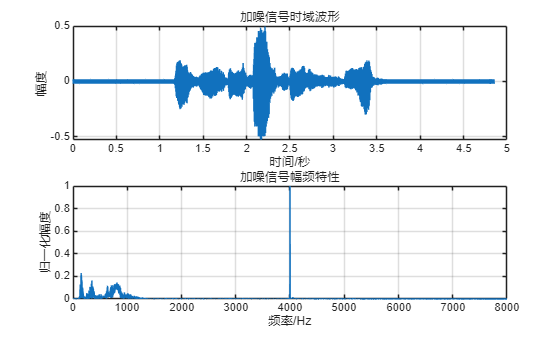

%% 要求：
% 正弦噪声信号Nt(t)=Acos(2πft)，f=4kHz，A=0.02。以dspx1.wav的采样频率将噪声信号数字化并混入音频信号之中
% 分别使用巴特沃兹滤波器、椭圆滤波器，设计出IIR数字滤波器，对音频进行去噪声处理。
% 设计的数字滤波器通带最大衰减δ_p≤3dB，阻带最小衰减δ_s≥40dB。注明所设计的滤波器类型（带通、带阻、低通）、以及设计的通带截止频率和阻带起始频率。
% 绘制出加噪信号时域波形及幅频图、滤波器幅频特性曲线、以及去噪后的时域波形及幅频图进行对比。
% 利用sound函数播放去噪后的音频。

clear; clc;
[y, Fs] = audioread('dspx1.wav');
n = length(y);
k = 0:n-1;

%% 添加正弦噪声
f_noise = 4000; 
A_noise = 0.02; 
noise = A_noise * cos(2*pi*f_noise*k*(1/Fs));
y_noise = y + noise'; % 因为 k 是行向量，y 是列向量，这里再转置成列向量再相加

%% 绘制加噪信号的时域波形和幅频图
x = (0:n-1)*(1/Fs);
figure;

% 时域波形
subplot(2,1,1);
plot(x, y_noise);
xlabel('时间/秒');
ylabel('幅度');
title('加噪信号时域波形');
grid on;

% 频域波形
Y_noise = fft(y_noise, n);
f = k*Fs/n;

subplot(2,1,2);
plot(f, abs(Y_noise)/(max(abs(Y_noise))));
xlabel('频率/Hz');
ylabel('归一化幅度');
title('加噪信号幅频特性');
axis([0, 8000, 0, 1]);
grid on;

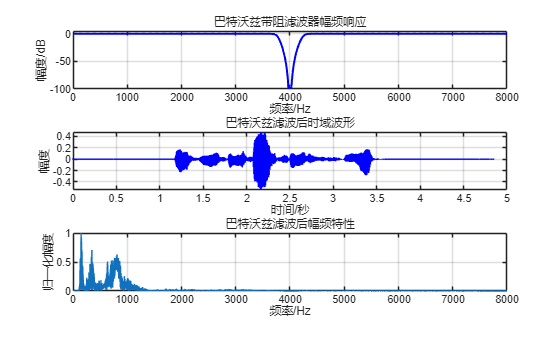

% 尽可能减少对非噪声信号的影响-带阻滤波器设计
Rp = 3;  % 通带最大衰减 3dB
Rs = 40; % 阻带最小衰减 40dB
fp1 = 3700;  % 下通带截止频率
fp2 = 4300;  % 上通带截止频率
fs1 = 3900;  % 下阻带起始频率
fs2 = 4100;  % 上阻带起始频率

% 数字频率归一化
wp = [fp1, fp2]*2*pi/Fs;  % 通带边界频率（归一化到0-pi）
ws = [fs1, fs2]*2*pi/Fs;  % 阻带边界频率（归一化到0-pi）

% 巴特沃兹带阻滤波器设计
[n1, wn1] = buttord(wp/pi, ws/pi, Rp, Rs);
[num1, den1] = butter(n1, wn1, 'stop');
[H1, w1] = freqz(num1, den1, 1024, Fs);
H1_DB = 20*log10(abs(H1)/max(abs(H1)));
y1 = filter(num1, den1, y_noise);
Y1 = fft(y1, n);

% 椭圆带阻滤波器设计
[n2, wn2] = ellipord(wp/pi, ws/pi, Rp, Rs);
[num2, den2] = ellip(n2, Rp, Rs, wn2, 'stop');
[H2, w2] = freqz(num2, den2, 1024, Fs);
H2_DB = 20*log10(abs(H2)/max(abs(H2)));
y2 = filter(num2, den2, y_noise);
Y2 = fft(y2, n);
figure;

% 巴特沃兹滤波器幅频特性
subplot(3,1,1);
plot(w1, H1_DB, 'b', 'LineWidth', 1.5);
xlabel('频率/Hz');
ylabel('幅度/dB');
title('巴特沃兹带阻滤波器幅频响应');
grid on;
axis([0, 8000, -100, 5]);

% 巴特沃兹滤波后信号时域波形
subplot(3,1,2);
plot(x, y1, 'b');
xlabel('时间/秒');
ylabel('幅度');
title('巴特沃兹滤波后时域波形');
grid on;

% 巴特沃兹滤波后信号频域特性
subplot(3,1,3);
plot(f, abs(Y1)/max(abs(Y1)));
xlabel('频率/Hz');
ylabel('归一化幅度');
title('巴特沃兹滤波后幅频特性');
axis([0, 8000, 0, 1]);
grid on;

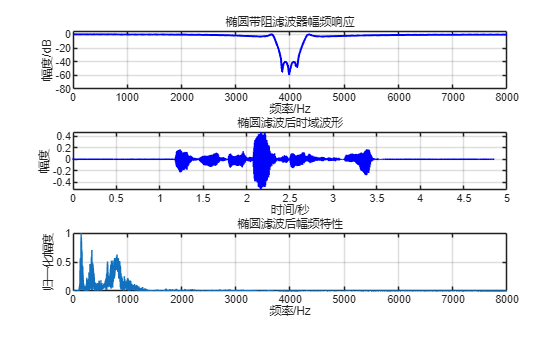

figure;

% 椭圆滤波器幅频特性
subplot(3,1,1);
plot(w2, H2_DB, 'b', 'LineWidth', 1.5);
xlabel('频率/Hz');
ylabel('幅度/dB');
title('椭圆带阻滤波器幅频响应');
grid on;
axis([0, 8000, -80, 5]);

% 椭圆滤波器滤波后信号时域波形
subplot(3,1,2);
plot(x, y2, 'b');
xlabel('时间/秒');
ylabel('幅度');
title('椭圆滤波后时域波形');
grid on;

% 椭圆滤波器滤波后信号频域特性
subplot(3,1,3);
plot(f, abs(Y2)/max(abs(Y2)));
xlabel('频率/Hz');
ylabel('归一化幅度');
title('椭圆滤波后幅频特性');
axis([0, 8000, 0, 1]);
grid on;

% sound(y_noise, Fs); % 加噪音频
% sound(y1, Fs); % 巴特沃斯滤波后的音频
% sound(y2, Fs); % 椭圆滤波后的音频